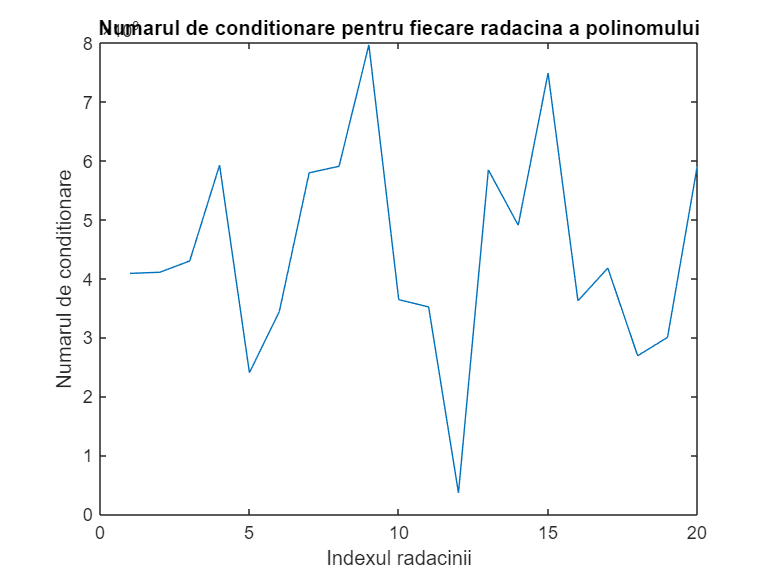

% Definim polinomul cu 20 de rădăcini
r = rand(20, 1); % generam 20 de numere aleatoare
p = poly(1:20); % definim polinomul cu aceste 20 de radacini

% Calculam rădăcinile polinomului
r = roots(p); % determinam rădăcinile polinomului

% Calculam numărul de condiționare pentru fiecare rădăcină
k = zeros(size(r)); % initializam un vector pentru a stoca numarul de conditionare pentru fiecare radacina
for i = 1:length(r)
    dp = 1e-10 * randn(size(p)); % generam o perturbare aleatoare a coeficientilor
    r_perturbed = roots(p + dp); % determinam rădăcinile polinomului perturbat
    k(i) = norm(r - r_perturbed) / norm(dp); % calculam numarul de conditionare
end

% Afisam graficul numărului de condiționare pentru fiecare rădăcină
plot(1:length(k), k);
xlabel('Indexul radacinii');
ylabel('Numarul de conditionare');
title('Numarul de conditionare pentru fiecare radacina a polinomului');